# MXB226 Case Study Modelling an Electronic Component

## Full Storage

[A,b] = full_storage;

## Packed Storage

%Write Code Here

## Band Storage

%RCM Storage
%Create a new A matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);

%factorise the A matrix with cholesky factorisation
A_RCM_cholesky = cholesky(A_RCM);

%solve with forward substitution and then backwards substitution

temperatures = forward_substitution(A_RCM_cholesky', b_rcm);
temperatures = backward_substitution(A_RCM_cholesky, temperatures);
temperatures = temperatures(reorder);

## Visualisation

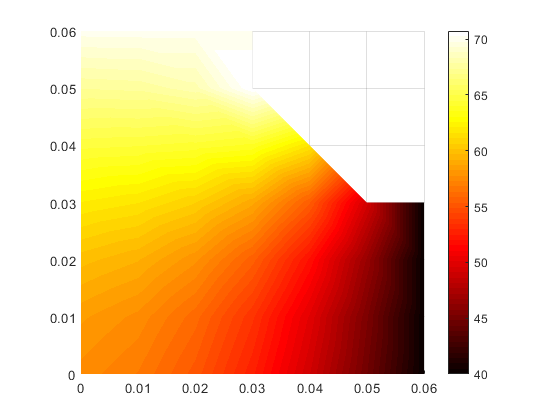

visualisation(temperatures)

## Sparse Storage

AMD = symamd(A);
A_AMD = A(AMD,AMD);
A_sparse = sparse(A_AMD);
b_sparse = b(AMD);

reorder = reorder_vector(AMD);

A_AMD_cholesky = cholesky(A_AMD);

%solve with forward substitution and then backwards substitution

temperatures = forward_substitution(A_AMD_cholesky', b_sparse);
temperatures = backward_substitution(A_AMD_cholesky, temperatures);
temperatures = temperatures(reorder);

## Visualisation

visualisation(temperatures)

## CSR Storage

%Write Code Here

## Visualisation

visualisation(temperatures)